# **Correlate Ca2+ across regions or Ca2+ and Behaviours **

To see whether different parts of the dendritic tree are correlated with each other, or if modulation of Ca2+ responses in specific areas of the tree correlate with behaviours, we can use correlation matrices. These correlation values can also be plotted on the tree, although most of the time only one row (or column) can be represented at the time.

## Grouping ROIs

Correlation can be done on single ROIs or we can use the binning tools to generate groups of ROIs and correlate them with each-other. For the binning, refer to the obj.prepare_binning documentation

## Signal preprocessing

However, a number of preprocessing steps can be used on Ca2+ signal:

- Signal normalization across ROIs. This is to minimize the effect of variations in signal amplitude due to instrumentation artefact. The best way to do it is to use obj.rescaled_traces (which itself required to run the peak detection and rescaling on the arboreal_experiment_object). If you plan to study the modulation of the signal between ROIs in relation to the cell average signal, this step is mandatory.

- We can smooth the signal. This will reduce the impact of imaging noise. Use obj.filter_win

- We can use only a subset of timepoints. Typically, we may want to use only the signal amplitude when there is a bAP. This requires to run the peak detection on the arboreal_experiment_object.

- We may want to focus on the signal modulation around the cell average instead of the signal magnitude itself. 

## Behaviour preprocessing

similarly, behaviour activity can be smoothed and/or detrended, which will usually affect correlation values

## Options Syntax.

To get the most up-to-date syntax, check set.cc_mode. Here is a summary

Correlation is computed using:

- A reference trace (located at index 1)

- The data you want to correlate (individual ROI, OR binned data, see below)

- Optionally, you can append population data

cc_mode is build by concatenating strings defining the timepoints to use (all of them or a subset), the traces to use (all of them or the binned data), whether you want to use population data too and whether you want to use some behavioural metrics. for example:

- 'groups_pop': correlation between binned median traces and population data using all timepoints

- 'active': correlation between all ROIs, using all timepoints when cell is active (i.e. during bAPs)

- 'peaks': correlation between all ROIS, only at peak time.

- 'encoder_peaks': correlation between all ROIS, only at peak time, AND only when running speed is high

- '~encoder_peaks': correlation between all ROIS, only at peak time, AND only when running speed is low

The reference (located at index 1 of the matrix) is either:

- The averaged somatic data when available (as defined by ref.indices.somatic_ROIs), or the nexus signal when somatic ROIS are not available

- The behaviour data if you specify 'behref', AND IF you pass a valid behaviour in obj.cc_mode (list available when typing obj.behaviours.types). eg: '~encoder_peaks_behref'

Correlation matrix can be generated using the entire trace (default) or a subset of timepoints:

- If cc_mode contains 'peaks', only the values at peak times (as defined by event.fitting.peak_pos) are used

- If cc_mode contains 'active', all the timepoints containing bAPs (as defined by event.fitting.t_win)

- If cc_mode contains 'quiet', all the timepoints between bAPs (as defined by ~event.fitting.t_win)

Correlation matrix can be generated using:

- every ROIs (except for excluded ROIs, indicated in ref.indices.valid_swc_rois)

- If cc_mode contains 'groups', using the median traces after categorical binning (as defined by binned_data.median_traces).

To include population data, include 'pop' in cc_mode.

# 1. Load experiment

Here we will directly use the existing arboreal_scan_object. For more advanced use cases, see Demo_FINAL_SERIES_OF_ANALYSIS

% folder_to_use = 'C:\Users\Antoine.Valera\MATLAB\newextraction_raw_zscored - All - Backup\2019-10-01_exp_1';
% obj = arboreal_scan_experiment(folder_to_use);

obj; % This is a current arboreal_scan_object in your base workspace

# 2. Define the Analysis Settings

## Arboreal Scan settings

%% The following settings will affect the events detected, the rescaling process, the event amplitude and median subtracted amplitude, as well as the excluded ROIs. Make sure this is all correct for you
obj.detrend                         = 0;            
obj.rendering                       = 1;
obj.time_smoothing                  = [-1.5, 0];

	INFO : No change detected in time smoothing


obj.thr_for_detection               = 0.2;
obj.bad_ROI_thr                     = 0.7;

## Set initial cross_correlation options for the demo

obj.cc_mode = '';

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces


obj.crosscorr_ref = '';

# 3. Correlate raw traces across all ROIs

## 3.1. Get default correlation

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the Cell-wide averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Current obj.cc_mode is : 
	INFO : Current obj.crosscorr_ref is :	

 !"#$	INFO : Correlation done between all valid ROIs, 
	Reference trace is the Cell-wide averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Correlation based on 


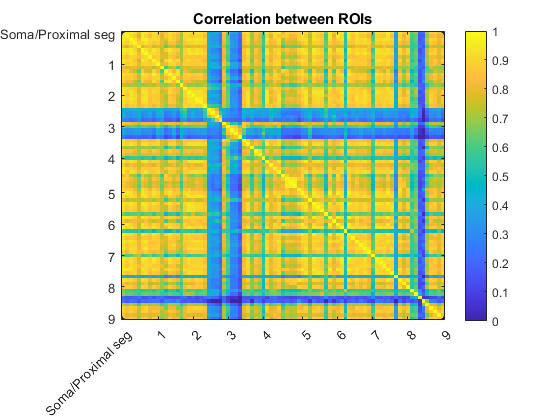

	MAJOR WARNING : To fix - Tree aspect forced as simple 



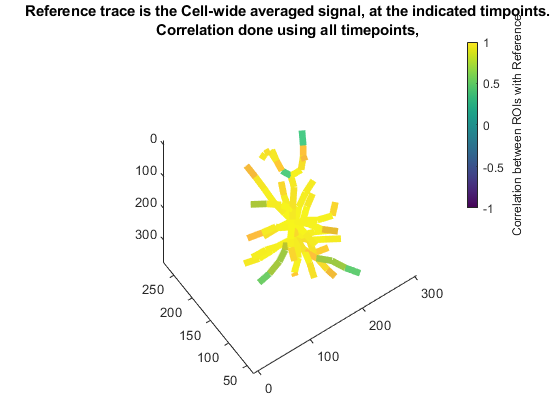

% This will use current "obj.cc_mode" and current "obj.crosscorr_ref" (printed in the command prompt FYI)
obj.get_correlations('');caxis([-1,1])

## 3.2. Get default correlation, but use average somatic signal as reference for the tree plot

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the Cell-wide averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Current obj.cc_mode is : 
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Correlation based on 


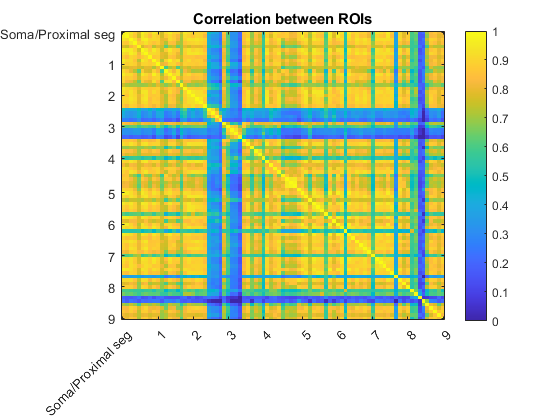

	MAJOR WARNING : To fix - Tree aspect forced as simple 



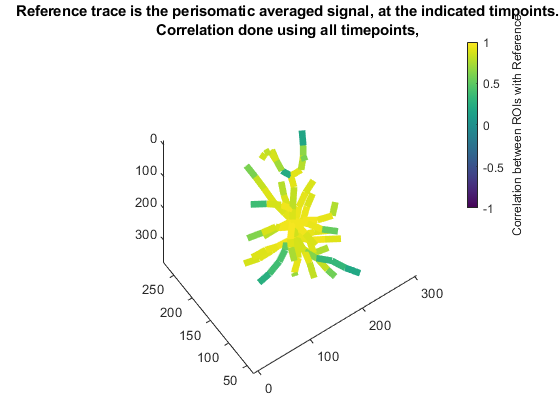

obj.get_correlations('','soma');caxis([-1,1])

## 3.3. Get default correlation, but use average cell signal as reference for the tree plot

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Current obj.cc_mode is : 
	INFO : Current obj.crosscorr_ref is :	

 !"#$	INFO : Correlation done between all valid ROIs, 
	Reference trace is the Cell-wide averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Correlation based on 


	MAJOR WARNING : To fix - Tree aspect forced as simple 



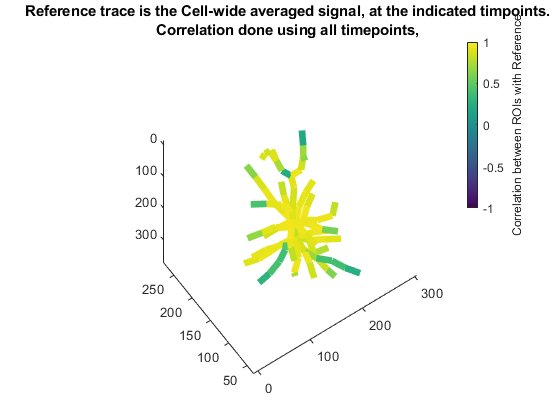

obj.get_correlations('','average');caxis([-1,1])

## 3.4. Get default correlation, but use ROI 48 as reference for the tree plot

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the Cell-wide averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Current obj.cc_mode is : 
	INFO : Current obj.crosscorr_ref is : 0
	INFO : Correlation done between all valid ROIs, 
	Reference trace is ROI # 48, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Correlation based on 


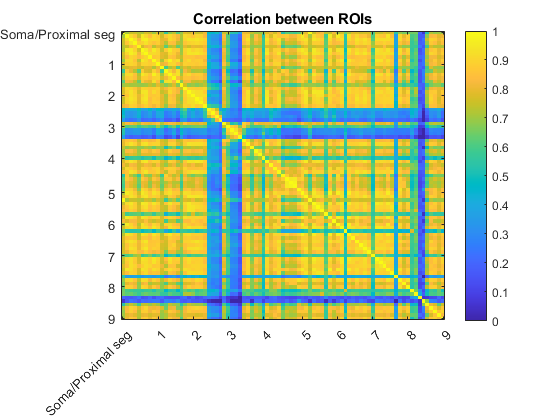

	MAJOR WARNING : To fix - Tree aspect forced as simple 



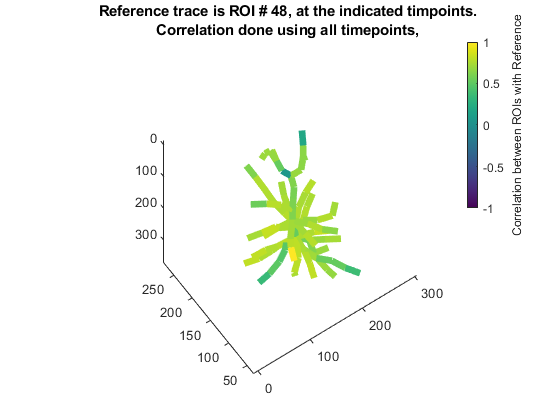

obj.get_correlations('', 48);caxis([-1,1])

# 4. Correlate detected Peaks across all ROIs

	INFO : Now detecting events with tree-wide pairwise correlation at least > 0.2 %
	INFO : 	Events detection is using PAIRWISE CORRELATION between all provided traces
			Epochs of correlated changes of activity across > 20 %% of the tree/pop will be considered as an event
			Events > 50 %% correlation will be considered as "global events". smaler correlations are local events

	WARNING : 	Maximal tree correlation is 89.4791%%. A values < 100%% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
				This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated

	INFO : 212 events have been detected
	INFO : Peak times were extracted on the scaled avrage of all traces, but usi

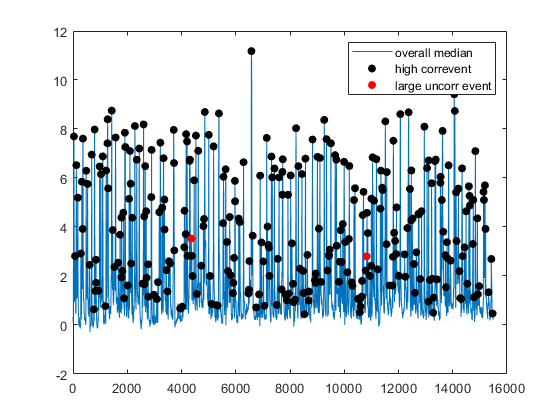

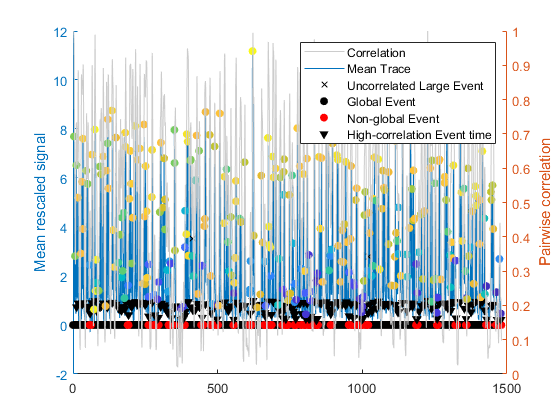

	INFO : 	Now detecting ROIs that are either,
			- so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
			- are member of batch_params.excluded_branches 
			Threshold for exclusion is 0.7 %



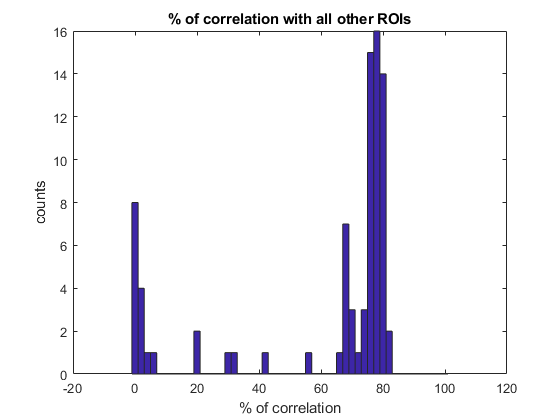

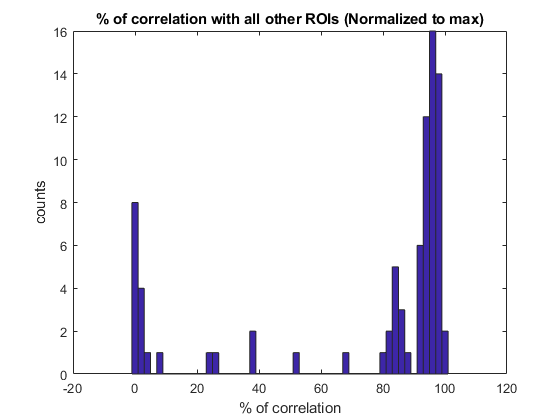

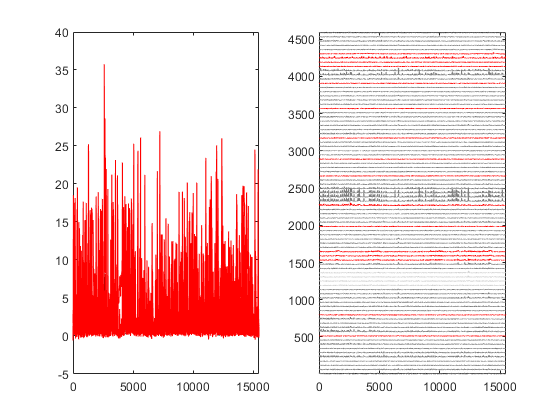

	MAJOR WARNING : To fix - Tree aspect forced as simple 



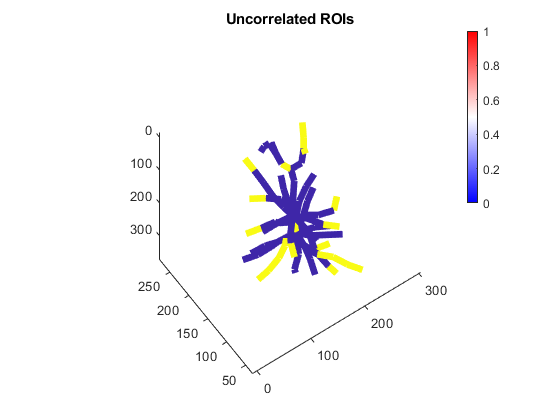

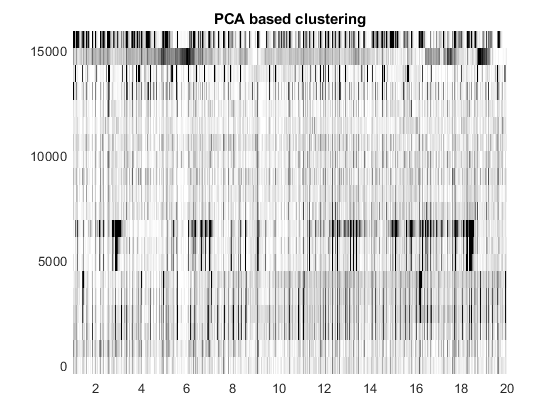

	INFO : Events were detected and obj.event field has been populated.


% Set the ref as the somatic average
obj.crosscorr_ref = 'soma';

% You need to run peak detection when using "peaks" and trace rescaling for
% median subtracted data
obj.find_events();

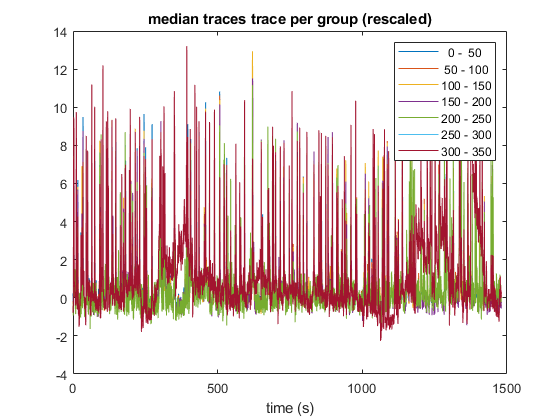

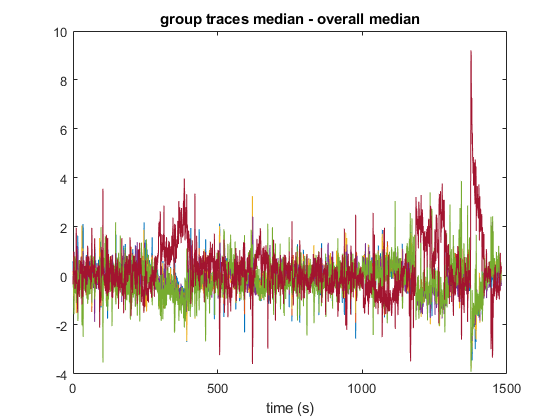

	INFO : obj.binned_data.median traces were computed using rescaled signals


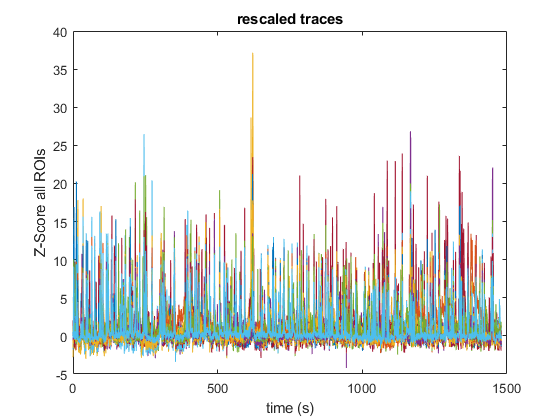

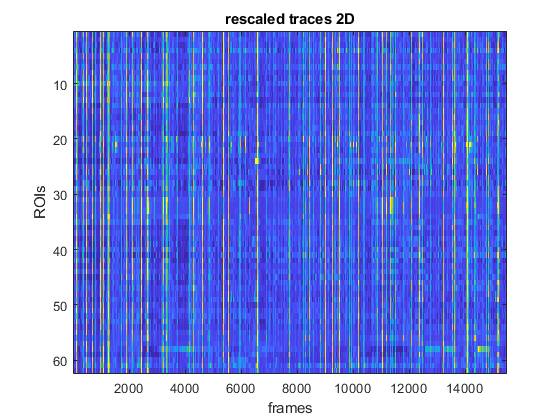

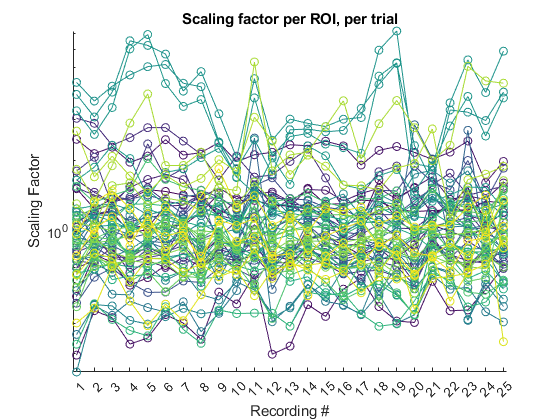

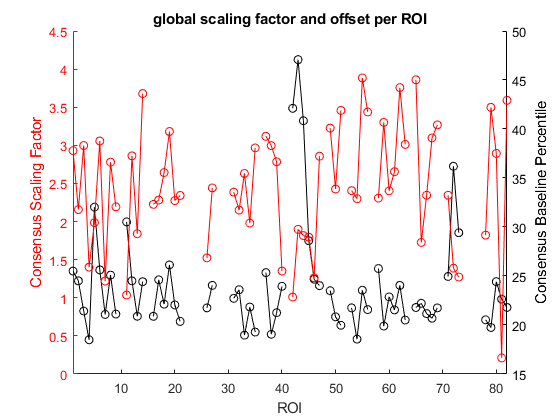

obj.rescale_traces();

## 4.1 Correlate Peaks amplitudes across ROIs

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Current obj.cc_mode is : peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
	INFO : Correlation based on peaks


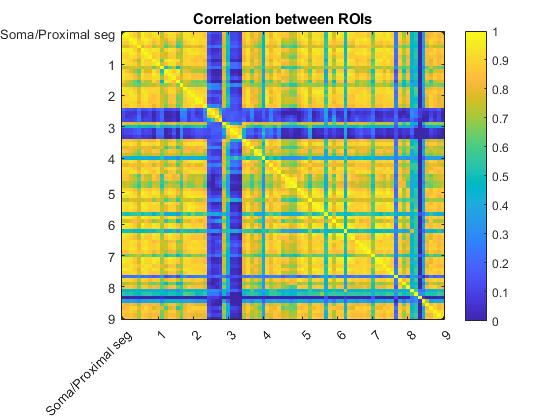

	MAJOR WARNING : To fix - Tree aspect forced as simple 



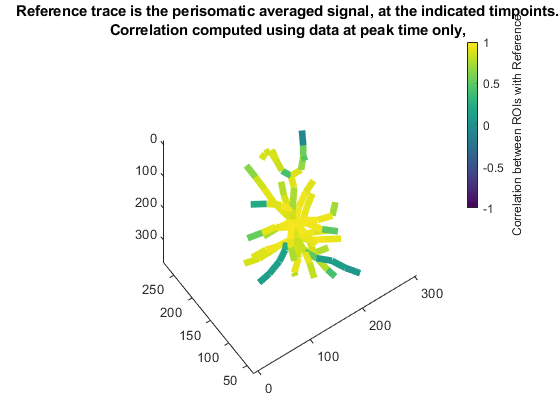

obj.get_correlations('peaks'); hold on;caxis([-1,1]);

## 4.2 Correlate Peaks modulation across ROIs

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
	INFO : Current obj.cc_mode is : subtracted_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces
	INFO : Correlation based on subtracted_peaks


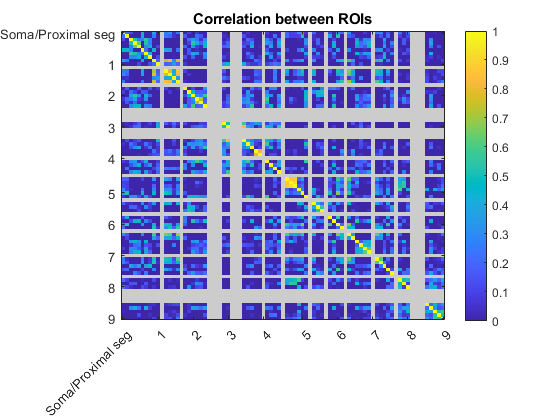

	MAJOR WARNING : To fix - Tree aspect forced as simple 



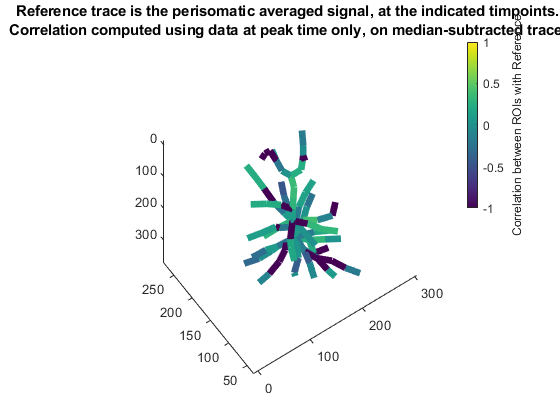

obj.get_correlations('subtracted_peaks'); hold on;caxis([-1,1]);

# 5. Correlate signal across groups of ROIs

## Set ROI groups

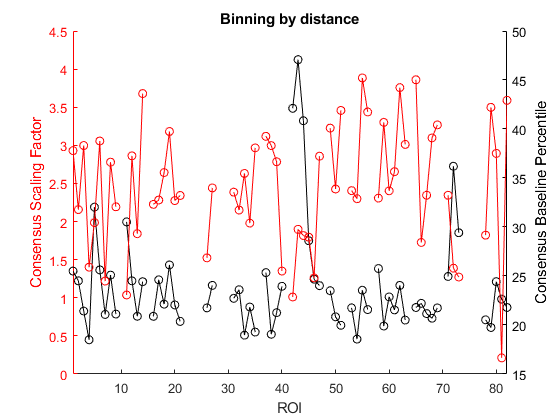

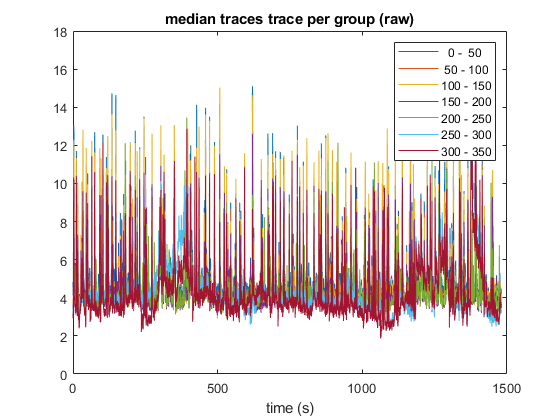

	INFO : obj.binned_data.median traces were computed using raw signals
	INFO : Bins were created. obj.binned_data is now available including group medians


% To run analysis on groups of ROIs, you need to define those groups
obj.prepare_binning({'distance',50});

	INFO : Now detecting events with tree-wide pairwise correlation at least > 0.2 %
	INFO : 	Events detection is using PAIRWISE CORRELATION between all provided traces
			Epochs of correlated changes of activity across > 20 %% of the tree/pop will be considered as an event
			Events > 50 %% correlation will be considered as "global events". smaler correlations are local events

	WARNING : 	Maximal tree correlation is 89.4791%%. A values < 100%% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
				This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated

	INFO : 212 events have been detected
	INFO : Peak times were extracted on the scaled avrage of all traces, but usi

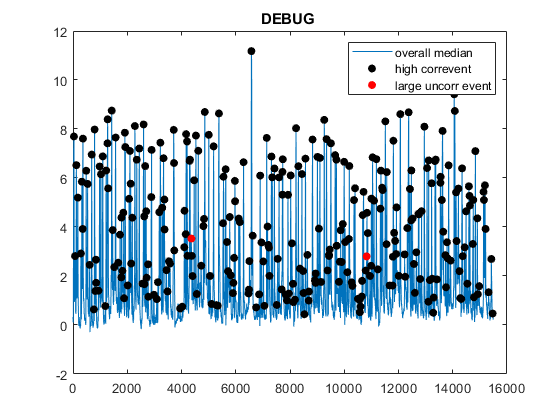

	INFO : 	Now detecting ROIs that are either,
			- so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
			- are member of batch_params.excluded_branches 
			Threshold for exclusion is 0.7 %



	MAJOR WARNING : To fix - Tree aspect forced as simple 



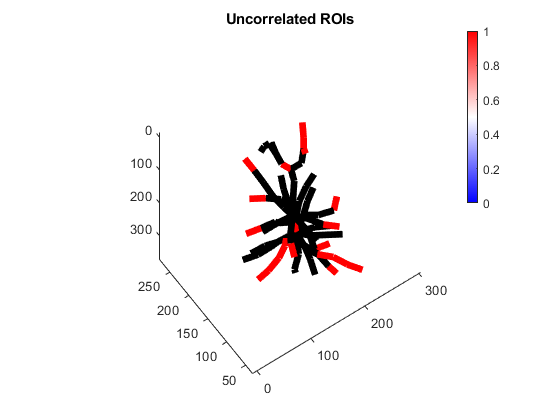

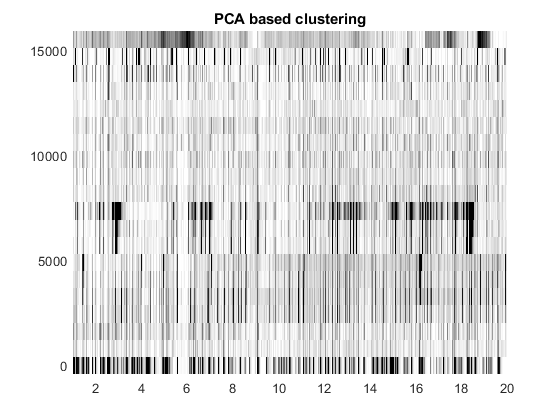

	INFO : Events were detected and obj.event field has been populated.



% You need to run peak detection when using "peaks" and trace rescaling for
% median subtracted data
obj.find_events();

	INFO : obj.binned_data.median traces were computed using rescaled signals


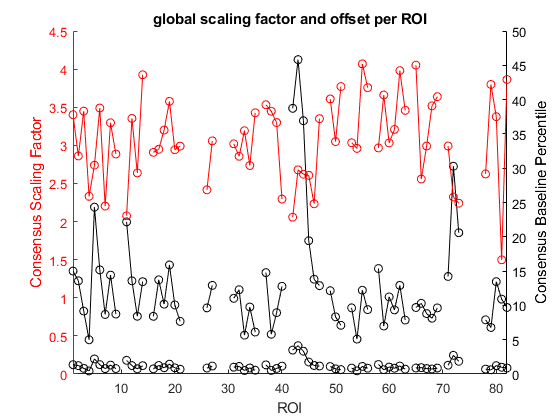

obj.rescale_traces();

## 5.1. Correlate whole traces, using the current groups defined in obj.binned_data

	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces
	INFO : Current obj.cc_mode is : groups
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Correlation based on groups


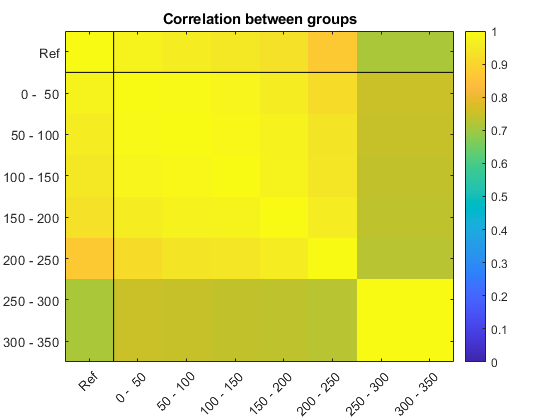

	MAJOR WARNING : To fix - Tree aspect forced as simple 



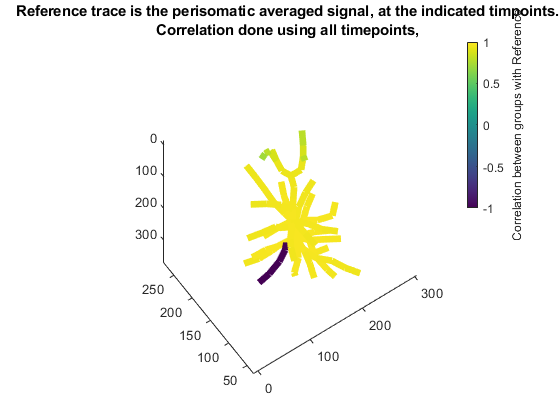

% Note that excluded branches will be grayed out
obj.get_correlations('groups'); hold on;caxis([-1,1]);

## 5.2. Correlate peaks amplitude, using the current groups defined in obj.binned_data

	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Current obj.cc_mode is : groups_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
	INFO : Correlation based on groups_peaks


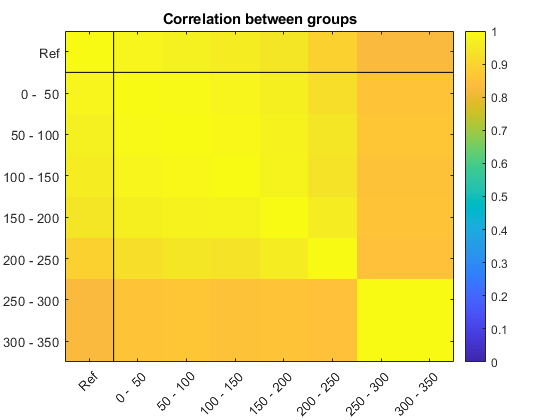

	MAJOR WARNING : To fix - Tree aspect forced as simple 



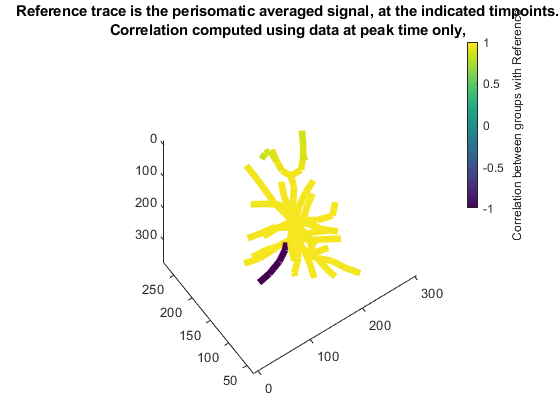

obj.get_correlations('groups_peaks'); hold on;caxis([-1,1]);

## 5.3. Correlate peaks modulation, using the current groups defined in obj.binned_data

	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
	INFO : Current obj.cc_mode is : groups_subtracted_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces
	INFO : Correlation based on groups_subtracted_peaks


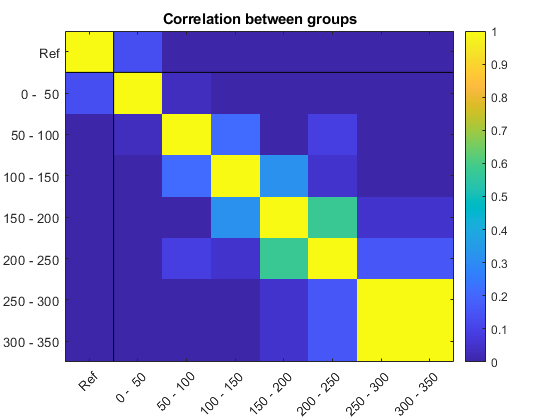

	MAJOR WARNING : To fix - Tree aspect forced as simple 



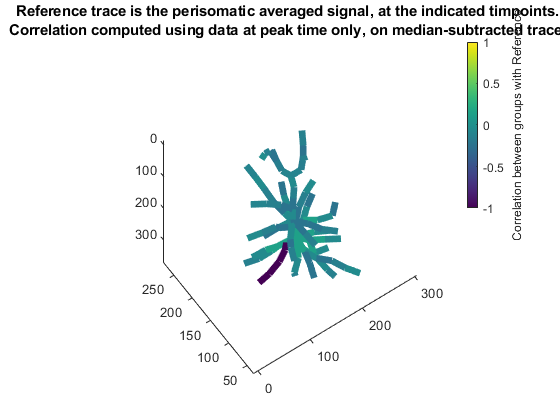

obj.get_correlations('groups_subtracted_peaks'); hold on;caxis([-1,1])

# 6. Subselect signal using activity window

Note that this requires peak detection, even when not setting the "peaks" flag

## 6.1. Use whole traces, but only during large events (but not only the peaks)

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using timepoints when the cell is quiet (i.e. between bAPs), 
	INFO : Current obj.cc_mode is : active
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using timepoints when the cell is active (i.e. during bAPs), 
	INFO : Correlation based on active


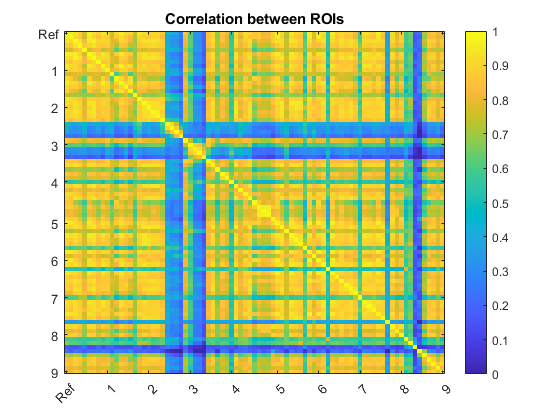

	MAJOR WARNING : To fix - Tree aspect forced as simple 



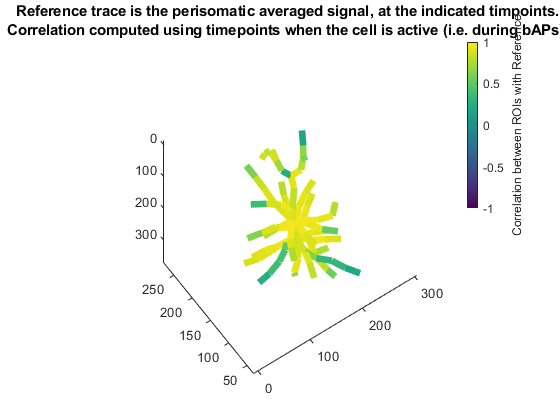

obj.get_correlations('active'); hold on;caxis([-1,1])

## 6.2. Use whole traces, but only between large events (background activity, possibly synaptic inputs)

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using timepoints when the cell is active (i.e. during bAPs), 
	INFO : Current obj.cc_mode is : quiet
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using timepoints when the cell is quiet (i.e. between bAPs), 
	INFO : Correlation based on quiet


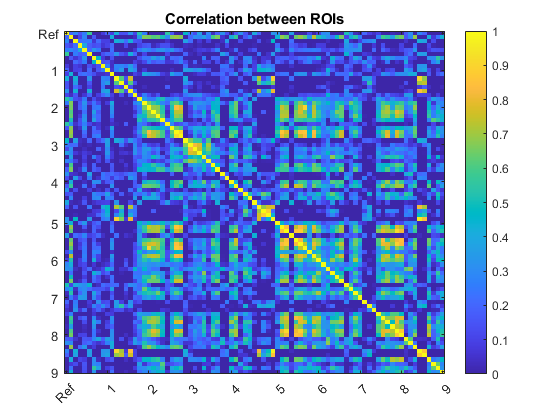

	MAJOR WARNING : To fix - Tree aspect forced as simple 



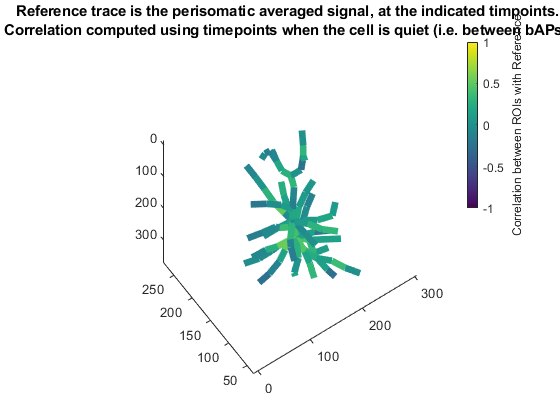

obj.get_correlations('quiet'); hold on;caxis([-1,1])

% Note that this is equivalent to obj.get_correlations('~active'); hold on;caxis([-1,1])

# 7. Subselect signal using activity window

## 7.1. Correlate signal modulation, but only on peaks and when the mouse is running

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder[3]" behaviour IS NOT ongoing.
	INFO : Current obj.cc_mode is : encoder_subtracted_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder" behaviour IS ongoing.
	INFO : Correlation based on encoder_subtracted_peaks


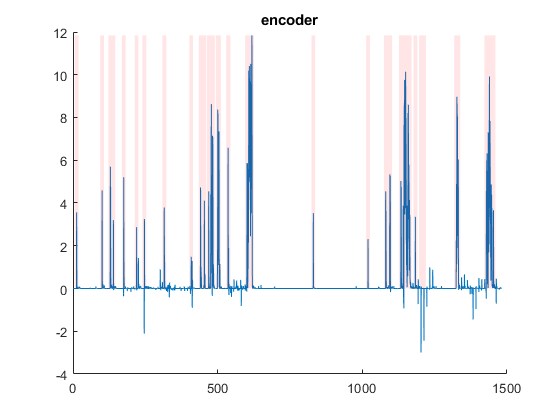

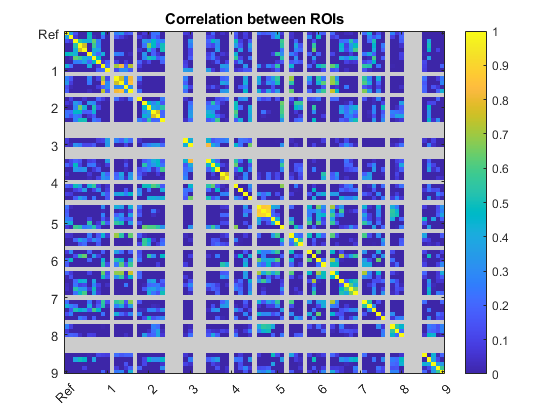

	MAJOR WARNING : To fix - Tree aspect forced as simple 



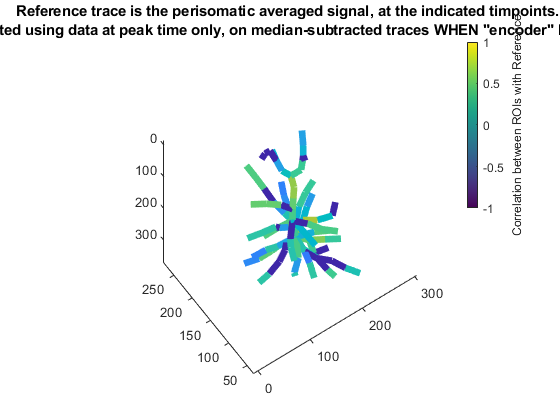

obj.get_correlations('encoder_subtracted_peaks'); hold on;caxis([-1,1])

## 7.2. Correlate signal modulation, but only on peaks and when the mouse is NOT running

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder" behaviour IS ongoing.
	INFO : Current obj.cc_mode is : ~encoder_subtracted_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder" behaviour IS NOT ongoing.
	INFO : Correlation based on ~encoder_subtracted_peaks


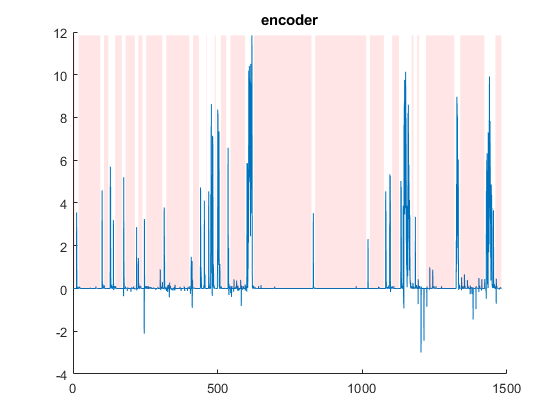

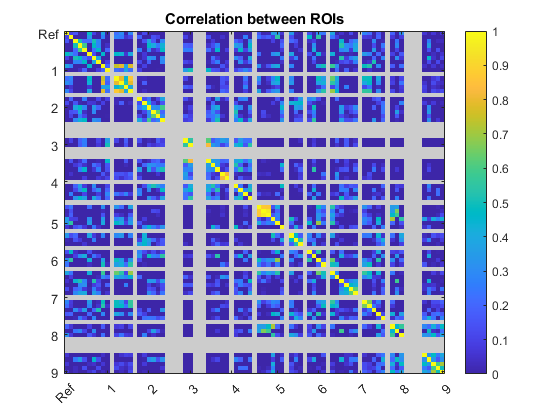

	MAJOR WARNING : To fix - Tree aspect forced as simple 



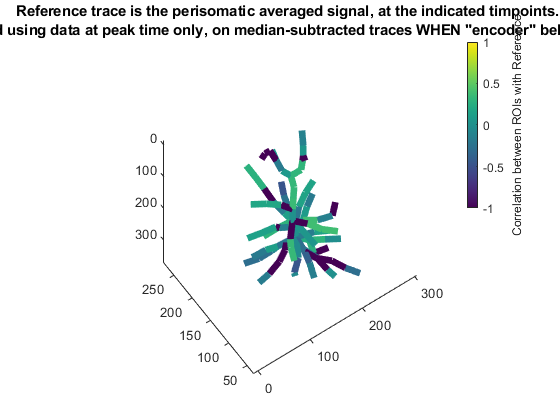

obj.get_correlations('~encoder_subtracted_peaks'); hold on;caxis([-1,1])

## 7.3. Correlate signal modulation, but only on peaks and when the mouse is NOT running

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder" behaviour IS NOT ongoing.
	INFO : Current obj.cc_mode is : ~encoder[3]_subtracted_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder[3]" behaviour IS NOT ongoing.
	INFO : Correlation based on ~encoder[3]_subtracted_peaks


	MAJOR WARNING : To fix - Tree aspect forced as simple 



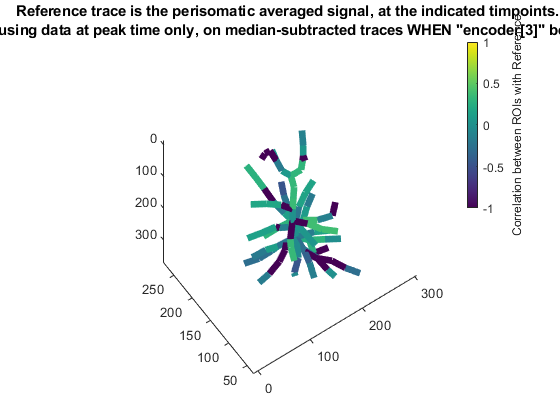

obj.get_correlations('encoder[3]_subtracted_peaks'); hold on;caxis([-1,1])

## 7.4 Correlate signal modulation preceding onsets by 5 s

	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, on median-subtracted traces WHEN "encoder[5,0,5]" behaviour IS ongoing.
	INFO : Current obj.cc_mode is : encoder[5,0,5]_peaks
	INFO : Current obj.crosscorr_ref is : 	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "encoder[5,0,5]" behaviour IS ongoing.
	INFO : Correlation based on encoder[5,0,5]_peaks


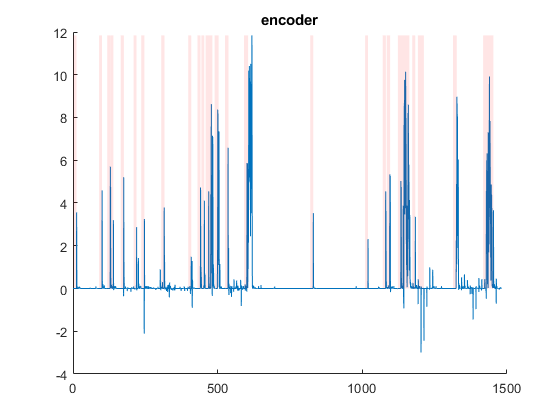

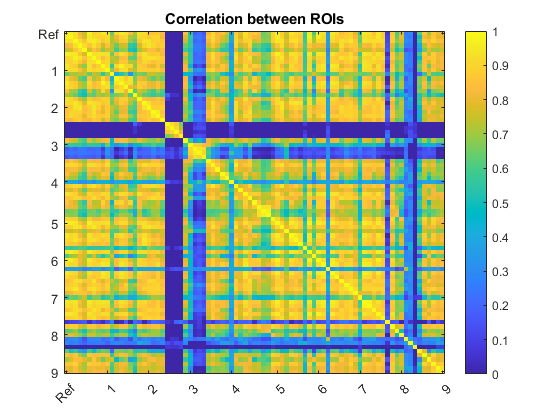

	MAJOR WARNING : To fix - Tree aspect forced as simple 



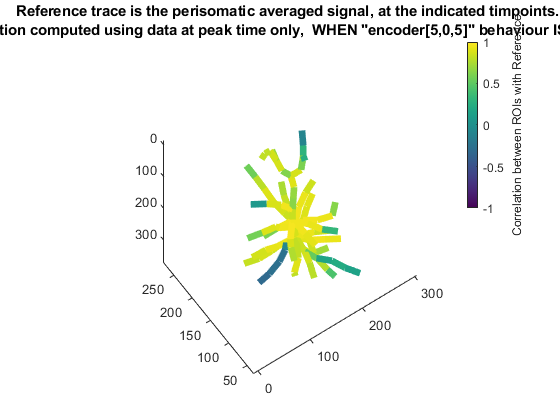

cross_corr = obj.get_correlations('encoder[5,0,5]_peaks'); hold on;caxis([-1,1]);

cross_corr = obj.get_correlations('subtracted_peaks')
% Note : you need to add to the path GenLouvain-master
[cluster_idx,Q] = genlouvain(double(cross_corr),[],[],1);
[a,b] = sort(cluster_idx);
figure(1008);clf();imagesc(cross_corr(b,b));xticks(1:numel(cluster_idx));xticklabels(num2str(a));hold on
yticks(1:numel(cluster_idx));yticklabels(num2str(a));

ax_tick = categorical(a);xticks(ax_tick)

cluster_idx = clusterdata(cross_corr,'Linkage', 'ward', 'MAXCLUST', 3);
[a,b] = sort(cluster_idx);
figure(1008);clf();imagesc(cross_corr(b,b))
obj.ref.plot_value_tree(cluster_idx,'','','CC-based clusters','',124,'','lines','discrete');
% R = unique(cluster_idx);
% colorbar('Ticks',R);
% caxis([nanmin(R)-0.5, nanmax(R)+0.5])
% colormap(lines(numel(unique(cluster_idx))));

% 
% [S,Q] = genlouvain(double(cross_corr),[],[],1);
% [a,b] = sort(S);
% figure(1008);clf();imagesc(cross_corr(b,b))
% obj.ref.plot_value_tree(split_values_per_voxel(S, obj.ref.header.res_list(1:obj.ref.indices.n_tree_ROIs,1), signal_indices),'','','','',124,'','lines');
% R = unique(S);
% colorbar('Ticks',R);
% caxis([nanmin(R)-0.5, nanmax(R)+0.5])
% colormap(lines(numel(unique(S))));